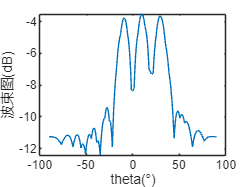

%https://blog.csdn.net/m0_55845774/article/details/143681209
%% CBF算法
clc;clear all;close all; 
ArrayNum = 10;               %阵面阵元的列数
c = 3e8;
f0 = 2e9;           %载频
lambda = c/f0;       %波长
d = lambda/2;        %阵元间距
fs = 10e6;            %快时间采样速率（系统带宽）
Ts = 1 / fs;
Du = 0.001;          %脉冲占空比
Tp = 2e-6;  % 脉宽
B = 5e6;
gamma = B / Tp;
N = 1;          % 快拍数
t = 0:Ts:(N-1)*Ts;
%% 回波信号为LFM信号
s = rect(t-Tp/2, Tp).*exp(1i*gamma*pi.*t.^2).*exp(1i*2*pi*f0.*t); % LFM信号

target_theta = [-10,10, 30];
%% 导向矢量
A = exp(-1i*2*pi*d*(1:ArrayNum)'*sind(target_theta)/lambda);

%% 接受数据X
X = A * s;

Theta = -90:0.1:90;
a = exp(-1i*2*pi*d*(1:ArrayNum)'*sind(Theta)/lambda);
p = abs(a' * A);
figure;
plot(Theta, 10*log10(p/max(p)));
xlabel('theta(°)');
ylabel('波束图(dB)');

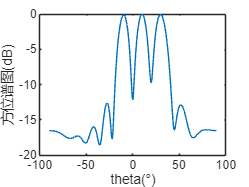


Rxx = X*X';
P = (1/N)*abs(diag(a' * Rxx * a));
figure;
plot(Theta, 10*log10(P/max(P)));
xlabel('theta(°)');
ylabel('方位谱图(dB)');


function y = rect(t, Tp)
    y = double((t >= -Tp/2) & (t < Tp/2));
end